signal = c;

Unrecognized function or variable 'c'.

S3 = zeros(N,N);
% FNr
FN = dftmtx(N); 
Fshift = zeros(N);
Fshift(1:N/2,N/2+1:end) = eye(N/2);
Fshift(N/2+1:end,1:N/2) = eye(N/2);
FN = Fshift*FN;
Taf = zeros(N);
temp_m = -M/2+1:M/2; 
for temp_1 = 1:N
    for temp_2 = 1:N
        temp_B = max(1-temp_1, 1-temp_2);
        temp_A = min (N-temp_1, N-temp_2);
        temp_n = temp_m((temp_m<=temp_A) & (temp_m>=temp_B));
        if isempty(temp_n)
            temp_taf = zeros(N,N);
        else
            temp_p = temp_1 + temp_n;
            temp_q = temp_2 + temp_n;
            temp_taf = zeros(N,N);
            temp_taf(temp_p(1):temp_p(end),temp_q(1):temp_q(end)) = eye(length(temp_q));
        end
        S3(temp_1,temp_2) = (FN*signal)'*temp_taf*(FN*signal); 
        if abs(temp_1-temp_2) < threshold
            Taf = temp_taf*0.1 + Taf;
        else
            Taf = temp_taf*10 + Taf;
        end
    end
end
figure
plot(diag(abs(fliplr(S3))));

epsilon = 0.1:0.1:0.5; % 相似性约束
delta = N^2*(1-epsilon/2).^2;
for e = epsilon
N^2*(1-e/2)^2
end

ans = 3.6966e+03

ans = 3.3178e+03

ans = 2.9594e+03

ans = 2.6214e+03

ans = 2304

clc; clear; close all;
addpath("function/");
N = 64;
M = 4;
threshold = 10;
fs = 64*1e6;
fc = 0e6;
B = 30e6;
T = 1e-6;
Es = 1; % 阻带能量约束定义
c = generator_LFM(fs,fc,B,T);
epsilon = 0.3; % 相似性约束
delta = N^2*(1-epsilon/2)^2;
% 初始化矩阵S
S = GenerateMatrixS(N, M, threshold);
S = (S + S')/2;
% S = S/max(abs(S),[],'all');
% 初始化矩阵R0
R0 = c*c';
% 初始化矩阵Rs
x = exp(1j*2*pi*rand(N,1));
x0 = x;
x = c;
% FNr
FN = dftmtx(N); 
Fshift = zeros(N);
Fshift(1:N/2,N/2+1:end) = eye(N/2);
Fshift(N/2+1:end,1:N/2) = eye(N/2);
FN = Fshift*FN;



SS = zeros(N);
% 计算循环谱矩阵
Taf = zeros(N);
temp_m = -M/2:M/2-1;
for temp_1 = -N/2:N/2-1
    for temp_2 = 1:N
        q1 = temp_1 + temp_2 + temp_m;
        q2 = temp_1 - temp_2 + temp_m;
        t1 = (0 <=q1 & q1 <= N-1) & (0 <= q2 & q2 <= N-1);
        q1 = q1 + 1;
        q2 = q2 + 1;
        temp_taf = zeros(N,N);
        temp_taf(q1(t1),q2(t1)) = 1;
%         temp_B = max(1-temp_1, 1-temp_2);
%         temp_A = min (N-temp_1, N-temp_2);
%         temp_n = temp_m((temp_m<=temp_A) & (temp_m>=temp_B));
%         if isempty(temp_n)
%             temp_taf = zeros(N,N);
%         else
%             temp_p = temp_1 + temp_n;
%             temp_q = temp_2 + temp_n;
%             temp_taf = zeros(N,N);
%             temp_taf(temp_p(1):temp_p(end),temp_q(1):temp_q(end)) = eye(length(temp_q));
%         end
        SS(temp_1+N/2+1,temp_2) = c'*FN'*temp_taf*FN*c;
        if abs(temp_1-temp_2) < threshold
            Taf = temp_taf*0.1 + Taf;
        else
            Taf = temp_taf*10 + Taf;
        end
    end
end
       % 循环谱计算矩阵 20240410 Modified   
        temp_m = -M/2+1:M/2;
        Taf_1 = cell((N+1)*N/2,1);
        Taf_2 = cell((N+1)*N/2,1);
        Taf = cell((N+1)*N/2,1);
        i_temp = 0;
        for temp_1 = 1:N
            for temp_2 = temp_1:N
                i_temp = i_temp + 1;
                temp_B = max(1-temp_1, 1-temp_2);
                temp_A = min (N-temp_1, N-temp_2);
                temp_n = temp_m((temp_m<=temp_A) & (temp_m>=temp_B));
                if isempty(temp_n)
                    temp_taf = zeros(N,N);
                else
                    temp_p = temp_1 + temp_n;
                    temp_q = temp_2 + temp_n;
                    temp_taf = zeros(N,N);
                    temp_taf(temp_p(1):temp_p(end),temp_q(1):temp_q(end)) = eye(length(temp_q));
                end
            end
        end

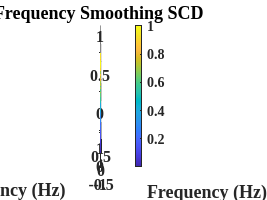

S = Analysis_CS_DFSM(fs, c, fs/128, 4, 'bool_draw', 1);

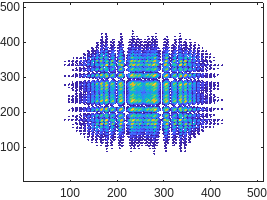

contour(real(S));

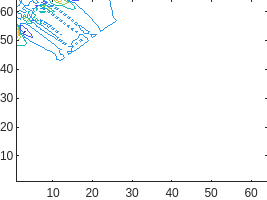

contour(real(SS));

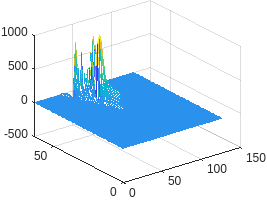

SS2 = fliplr(SS);
mesh(real([SS2,SS]));